# 383L Project

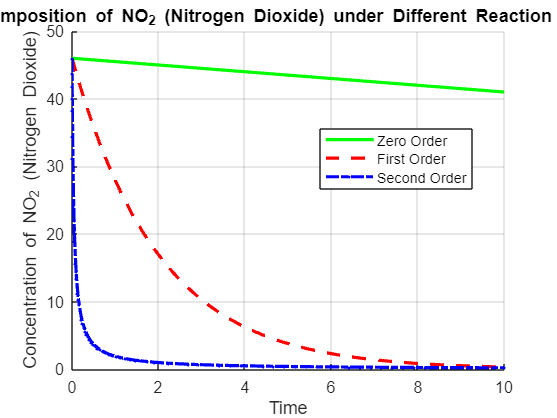

% The molar mass of Nitrogen Dioxide = 46.0055 g/mol which is Inital
% Conditional
A0 = 46.0055; % Initial concentration

% Time span for the simulation, from 0 to 10 units of time
tspan = [0 10];

%  The rate of formation of N2O4 ( g ) is .5s^-1
k = .5; % Adjust as necessary for your simulation

% Define the ODEs for each reaction order
% Zero-order reaction [A] = −kt + [A]0
zeroOrderODE = @(t, A) -k;
% First-order reaction ln[A] = −kt + ln[A]0 -> [A] = exp(ln[A]0 - kt)
firstOrderODE = @(t, A) -k * A;
% Second-order reaction 1/[A] = kt + 1/[A]0 -> [A] = 1/(kt + 1/NO2_0)
secondOrderODE = @(t, A) -k * A^2;

% Solve the ODE using ode45 for each reaction order
[t_zero, A_zero] = ode45(zeroOrderODE, tspan, A0);
[t_first, A_first] = ode45(firstOrderODE, tspan, A0);
[t_second, A_second] = ode45(secondOrderODE, tspan, A0);

% Plotting the results
figure;
hold on;
plot(t_zero, A_zero, 'g', 'LineWidth', 2, 'DisplayName', 'Zero Order');
plot(t_first, A_first, 'r--', 'LineWidth', 2, 'DisplayName', 'First Order');
plot(t_second, A_second, 'b-..', 'LineWidth', 2, 'DisplayName', 'Second Order');
xlabel('Time');
ylabel('Concentration of NO_2 (Nitrogen Dioxide)');
title('Decomposition of NO_2 (Nitrogen Dioxide) under Different Reaction Orders');
legend('Zero Order', 'First Order', 'Second Order', 'location','best')
grid on;
hold off;

github

copyfile(fullfile(matlabroot,'toolbox','shared','cmlink','git','auxiliary_files', ...
'mwgitattributes'),fullfile(pwd,'.gitattributes'))